# 4F2 CW1 Report notebook

## 1)

### i)

  
$$G = \frac{c_p}{ms^2 + c_vs + c_p}
$$



$$G_{\mathrm{nom}} =\frac{1}{s^2 +s+1}$$


gain margin = $\infty$

phase margin = ${90}^{\circ }$

any gain k > -1 guarentees stability due to nyquist stability criterion

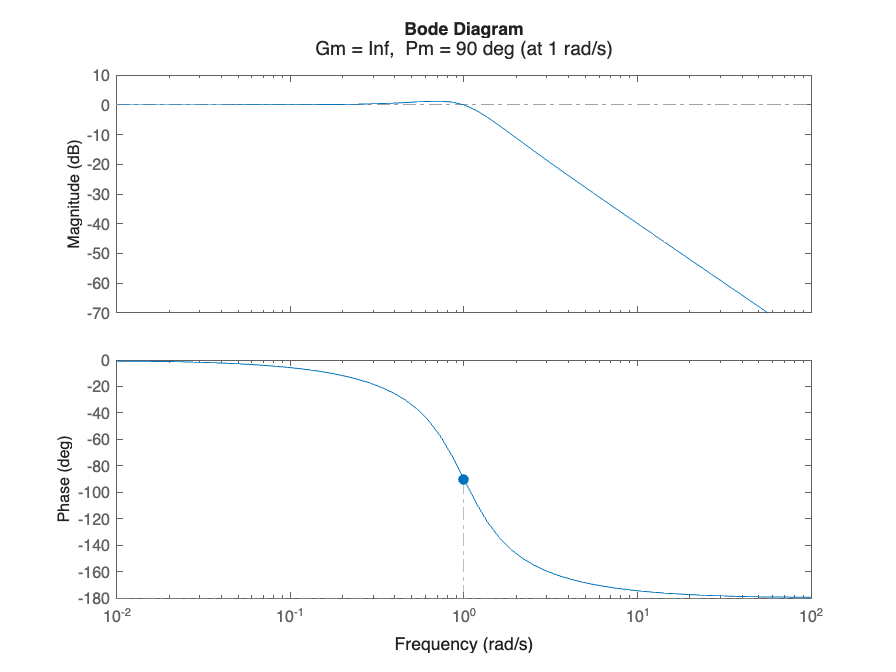

m=1;
cp=1; % +-0.075
cv=1; % +-0.1

G_nom = tf(cp, [m, cv, cp]);

% bode(G_nom);
figure
margin(G_nom)

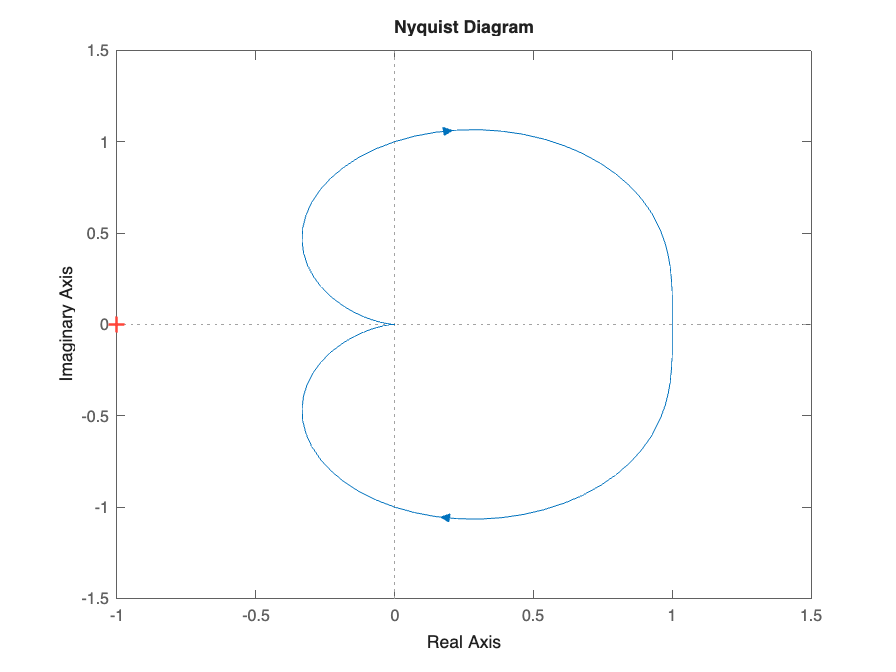


figure
nyquist(G_nom);

### ii)

since TF for tracking performance and disturbance responce is identicall higher k will assure better traccking but also means higher gain of the disturbance to y.

higher value of K => smaller statedy state error but the responce becomes more oscillatory.

poles moves up and down 90 deg 

if k is ganative the system stabalises but with ss error > 1 so if the reference is inverted it could be stabalised with less oscillation while having low ss error with givern (since r is -r)

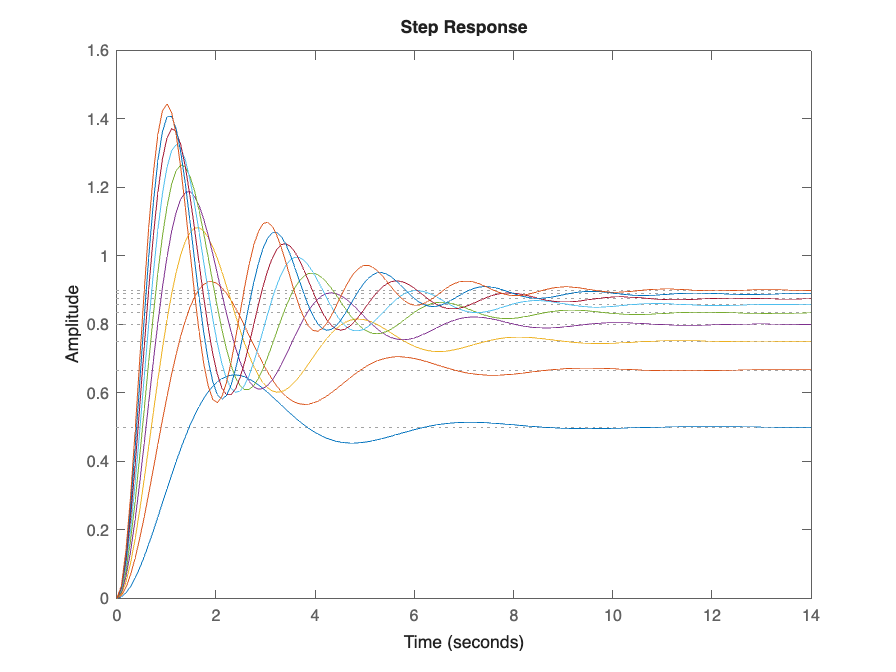

omega = 2*pi*1e5;
d = tf(omega, [1, 0, omega^2]);
s = tf('s');
% figure(3)
% rlocus(G_nom);

figure
% step(((-0.1*G_nom)/(1+-0.1*G_nom)));
% hold on;
for k=1:1:9
    % y = -((k*G_nom)/(1+k*G_nom))*d;
    step(((k*G_nom)/(1+k*G_nom)));
    hold on;
end

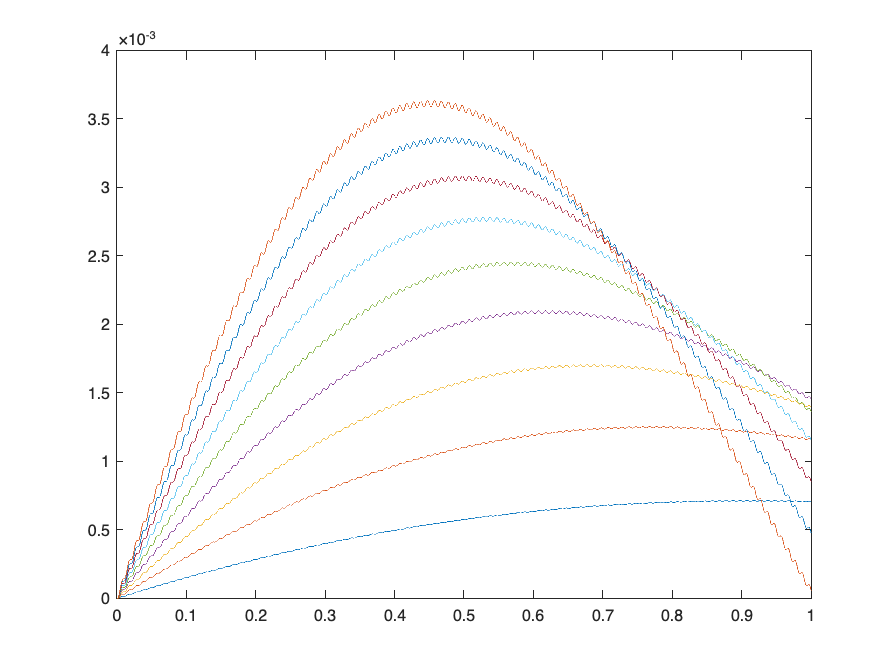


figure
t = 0:1e-4:10e-1;
omega = 2*pi*1e2;
u = sin(omega*t);
% d = tf(omega, [1, 0, omega^2]);

% step = tf(1, [1, 0]);
for k=1:1:9
    % k= -k;
    % y = -((k*G_nom)/(1+k*G_nom))*d;
    % step(((k*G_nom)/(1+k*G_nom)))
    [yout, time] = lsim(((k*G_nom)/(1+k*G_nom)), u, t);
    plot(time, yout, 'DisplayName', num2str(k))
    hold on;
end

### iii)

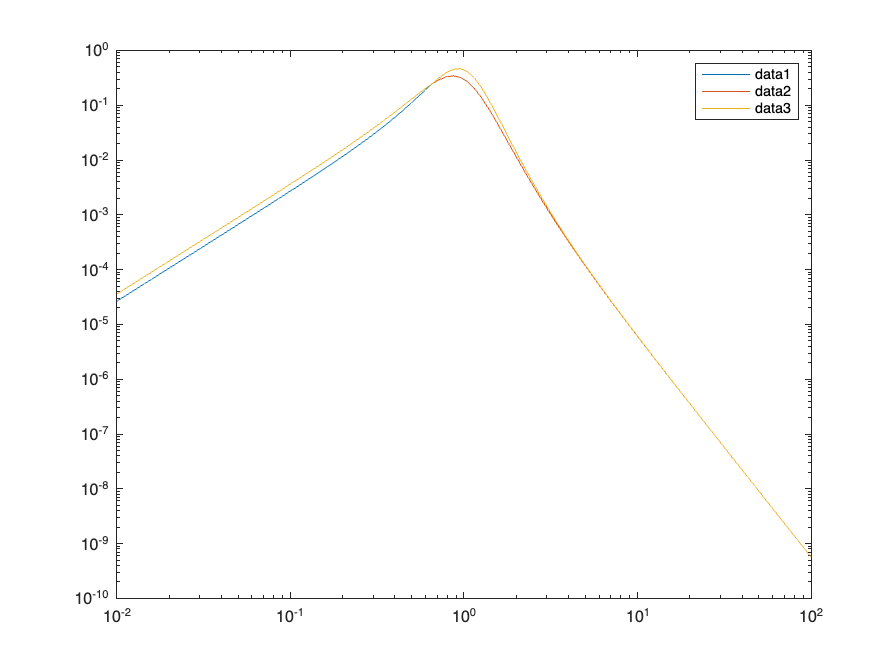

delcp_range = -0.075:0.0075:	0.075;
delcv_range = -0.1:0.01:0.1;

w = logspace(-2, 2, 100);
gain = zeros(size(w));

figure
axes('XScale', 'log', 'YScale', 'log')
delcp = delcp_range(end);
delcv = delcv_range(1);
gain = ( ...
            ((delcp^2).*(w.^4) + (w.^2).*(delcp-delcv)^2) ...
            ./ ...
            ((1-w.^2+w.^4).*(((1+delcv)^2)*(w.^2) + (1+delcp-w.^2).^2)) ...
            ).^0.5;
loglog(w, 10*gain.^2);
hold on;

delcp = delcp_range(1);
delcv = delcv_range(end);
gain = ( ...
            ((delcp^2).*(w.^4) + (w.^2).*(delcp-delcv)^2) ...
            ./ ...
            ((1-w.^2+w.^4).*(((1+delcv)^2)*(w.^2) + (1+delcp-w.^2).^2)) ...
            ).^0.5;
loglog(w, 10*gain.^2);
hold on;

for delcp = delcp_range
    for delcv = delcv_range
        new_gain = ( ...
            ((delcp^2).*(w.^4) + (w.^2).*(delcp-delcv)^2) ...
            ./ ...
            ((1-w.^2+w.^4).*(((1+delcv)^2)*(w.^2) + (1+delcp-w.^2).^2)) ...
            ).^0.5;
        % loglog(w, new_gain);
        gain = max(gain, new_gain);
        hold on;
    end
end
loglog(w, 10*gain.^2);

legend

### iv)

m=1;
cp=1; % +-0.075
cv=1; % +-0.1
dcp = 0.075

dcp = 0.0750

dcv = 0.1

dcv = 0.1000


w_cr = sqrt(dcp/ (dcp + dcv))

w_cr = 0.6547

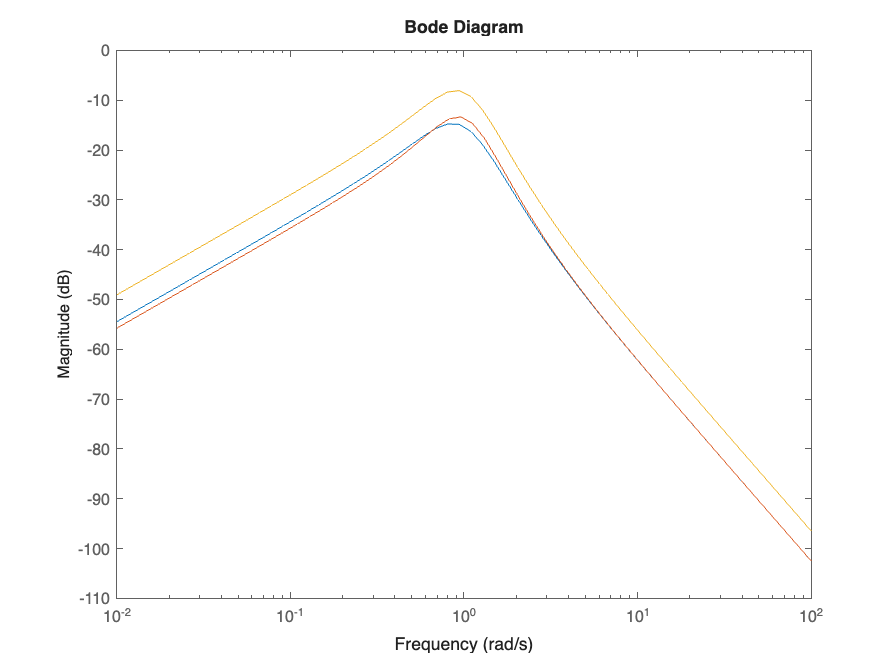


delG1 = tf(cp-dcp, [m, cv+dcv, cp-dcp]) - G_nom;
delG2 = G_nom - tf(cp+dcp, [m, cv-dcv, cp+dcp]);
% b = max([delG2, delG1]);

W2p = ((s) / (s +1.15)^3);
W2p = W2p* hinfnorm(delG2)/hinfnorm(W2p);

% k = evalfr(delG1/delG2, 1e-90)

figure
legend
bodemag(delG1, delG2, delG1+delG2)


$$$|\Delta\;G|=\sqrt{ \frac{\Delta \;c_p^2 \omega^4 +\omega^2 {\left(\Delta \;c_p -\Delta \;c_v \right)}^2 }{\left(\omega^4 -\omega^2 +1\right)\left({\left(1+\Delta \;c_v \right)}^2 \omega^2 +{\left(1+\Delta {\;c}_p -\omega^2 \right)}^2 \right)}}$$$


the magniture of DG in the range of cp = +-0.075, cv= +- 0.1 only has once point where the gradient of this valeue is 0 (cp = 0 , cv=0) wrt to dcp dcv and since the magnitude should alway be a positive value the values at the corner  the range must be a maxium at a gven frequency w

Thus this gives

b = 

for W < W_cr Max of above is obtained with dcp = -0.075 dcv = 0.1

and for W > W_cr Max is at dcp = 0.075, dcv= - 0.1

so a sinple and propper bound to be used for W2 can be obtained by adding the 2 trasfer function together

### V)

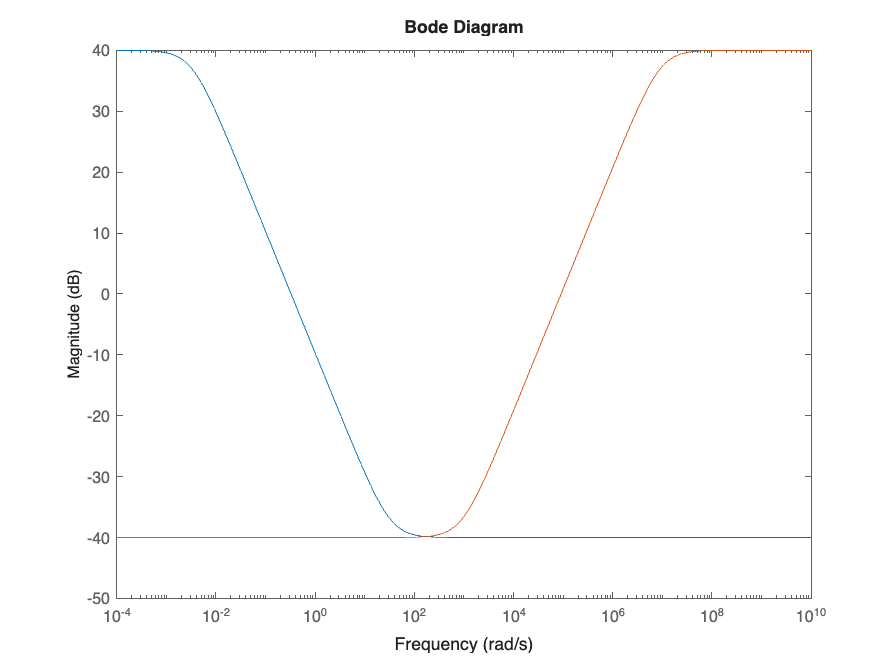

s = tf('s');
W1 = makeweight(100, [6*pi, 0.02], 0.01);
W2 = delG1+delG2;
% W2 = delG2*1.16;
% W2 = hinfnorm(delG2);
% W2 = W2p;
W3 = makeweight(0.01, [500*pi, 0.02], 100);

figure
legend()
bodemag(W1, W3)


P = augw(G_nom,W1,[] ,W3);
[Knom,CL,gamma] = hinfsyn(P, 1, 1);
gamma

gamma = 0.0115

P = augw(G_nom,W1,W2,W3);
[K,CL,gamma] = hinfsyn(P, 1, 1);
gamma

gamma = 0.2619


cp = ureal('cp', 1, 'PlusMinus', 0.075);
cv = ureal('cv', 1, 'PlusMinus', 0.1);
s = tf('s');
G_nom_u = cp/(s^2 + cv*s + cp);

T_r = feedback(K*G_nom_u, 1);
T_n = feedback(Knom*G_nom_u, 1);

T_nom_r = feedback(K*G_nom, 1);
T_nom_n = feedback(Knom*G_nom, 1);

robstab(T_r)

ans = struct with fields:
           LowerBound: 11.1242
           UpperBound: 11.1436
    CriticalFrequency: 3.3400



robstab(T_n)

ans = struct with fields:
           LowerBound: 13.0183
           UpperBound: 13.0381
    CriticalFrequency: 1.1438


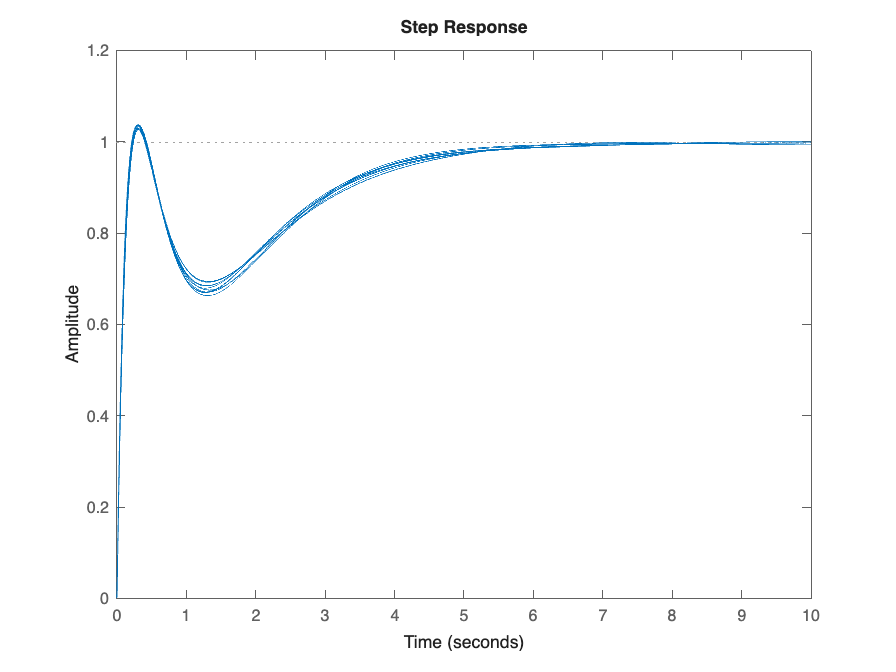


T_r1 = feedback(K*(G_nom+delG1), 1);
T_n1 = feedback(Knom*(G_nom+delG1), 1);

T_r2 = feedback(K*(G_nom-delG2), 1);
T_n2 = feedback(Knom*(G_nom-delG2), 1);

stepplot(usample(T_r, 10), 10)

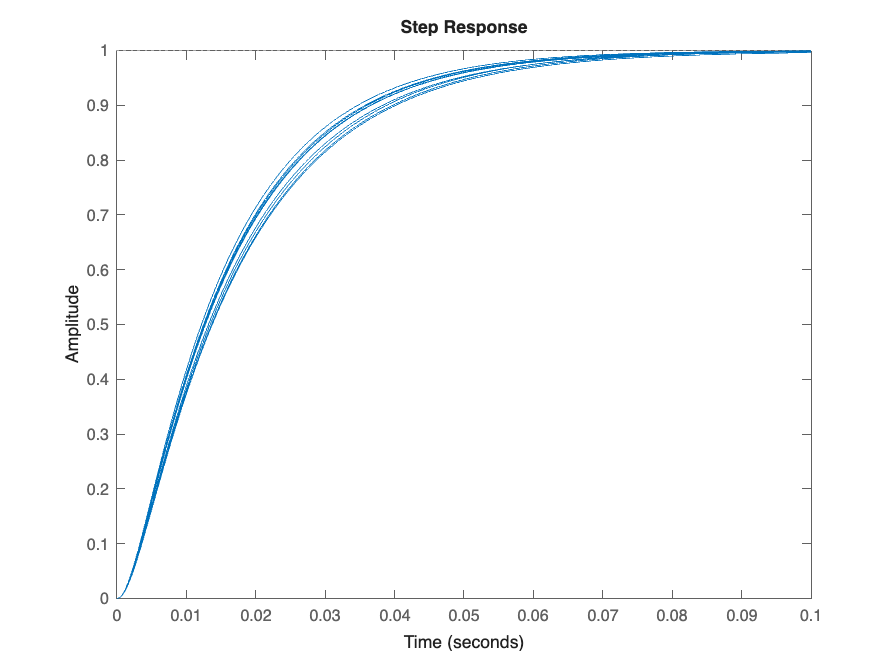

stepplot(usample(T_n, 10), .1)

% 
% figure(7)
% hold on
% stepplot(T_r1-T_nom_r, .1)
% stepplot(T_r2-T_nom_r, .1)
% 
% figure(8)
% hold on
% stepplot(T_n1-T_nom_n, .1)
% stepplot(T_n2-T_nom_n, .1)

% t=0:0.01:10;
% u = sin(t);
% figure
% for i=1:1:10
%     [yout, t]= lsim(usample(T_n, 1)-T_nom_n, u, t);
%     plot(t, yout)
%     hold on 
% end
% 
% figure
% for i=1:1:10
%     [yout, t]= lsim(usample(T_r, 1)-T_nom_r, u, t);
%     plot(t, yout)
%     hold on 
% end
% normal = 
% 
% lsim()

% P = 1/(1+tf(K*G_nom));
% hinfnorm((1+tf(K*G_nom)/tf(K)))
% P = 1/(1+tf(Knom*G_nom));
% hinfnorm((1+tf(Knom*G_nom)/tf(Knom)))
% bode((1+tf(Knom*G_nom)/tf(Knom)))

small gain theorem is a sufficient condition for stability and thus from robustness with parametric uncertainty in this The controler designed without any constrain on the control effort performs better interms of robustness (and tracking) but the one with the condition inforced is guarenteed by small gain theoremt to be stable

by looking at the nyquist plot of the controller designed without any W2 is stable for given range of parameter uncertainty and performs better to this controller should eb used in stead. since the robustness can also be tested retrospectively.

## 2

### i)

#### a)

Gmat = im not writing tha here

#### b)

tau = 0.05;
s = tf('s');
X = 1/(tau*s + 1)^2;
W = 1/(0.5*s +1)^4;

G = [[X*s^2  -X  -X  0];
     [X (s^(-2))*(1/X - X) -(s^(-2))*X (s^(-2))];
     [W*(1-X) -W*(s^(-2))*(1/X - X) W*(s^(-2))*X W*(-s^(-2))];
     [W*(s^2)*X W*(1-X) -W*X 0]];

Gss = ss(makeStateSpace(G), 'minimal');

% sigma(Gss);

%%%
A = Gss.A;
B = Gss.B;
C = Gss.C;
D = Gss.D;
Br = B(:, 1:2);
Bu = B(:, 3:4);
% Dr = D(:, 1:2);
% Du = D(:, 3:4);
Dry = D(1:2, 1:2);
Duy = D(1:2, 3:4);
Dre = D(3:4, 1:2);
Due = D(3:4, 3:4);
Cy = C(1:2, :);
Ce = C(3:4, :);

[n, ~] = size(A)

n = 12


gamma=0;
cvx_begin sdp
    variable Y(n, n) symmetric
    variable Z(2, n)
    variable gamma
    minimize(gamma)
    LMI1 = Y>0

 
Constraint accepted
 


    LMI2 = gamma > 0.1

 
Constraint accepted
 


    LMI3 = [[Y*A' +  A*Y + Z'*Bu' + Bu*Z , Br, Y*Ce' + Z'*Due' ];
                [ Br', -gamma*eye(2) , Dre'];
                [ Ce*Y + Due*Z , Dre , -gamma*eye(2)]] < 0;

cvx_end

 
Calling SDPT3 4.0: 215 variables, 103 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 103
 dim. of sdp    var  = 28,   num. of sdp  blk  =  2
 dim. of linear var  =  1
 number of nearly dependent constraints = 1
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|6.0e+02|4.1e+00|3.9e+04| 4.266667e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.461|0.859|3.2e+02|5.8e-01|2.3e+04|-8.083776e+02 -1.876968e+02| 0:0:00| chol  1  1 
 2|0

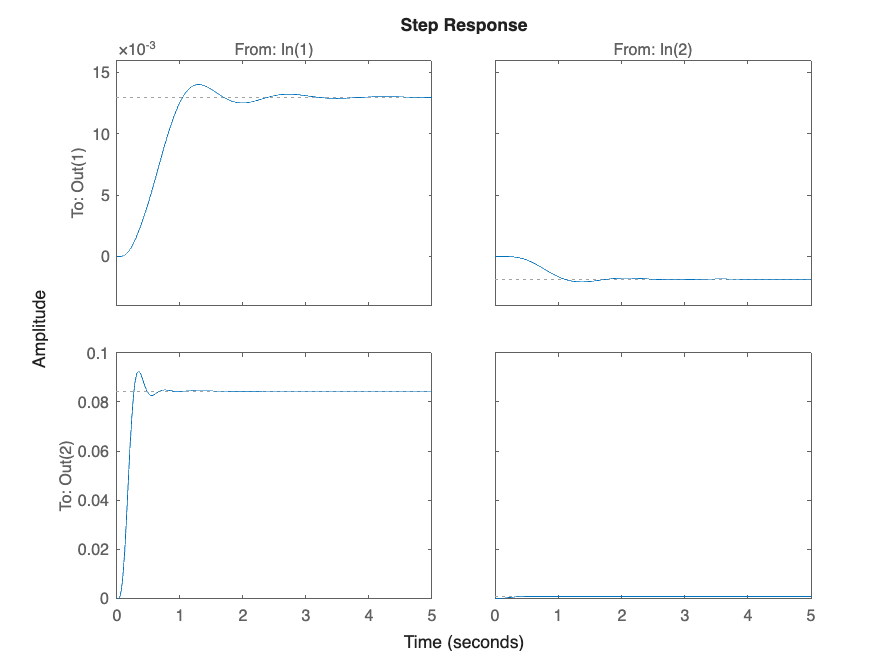


K = Z/Y;

G_feedback = ss((A+Bu*K), Br, (Ce + Due*K), Dre);
K_full = [zeros(2, n); K];
G_full_fb = ss(A+B*K_full, B, C+D*K_full, D);


step(G_feedback)

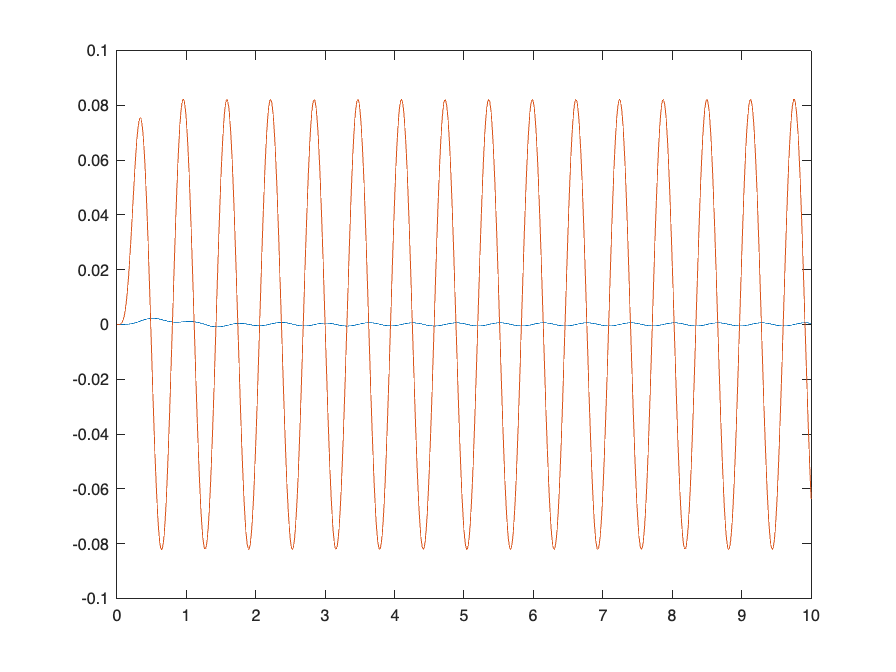

% step(G_full_fb)

figure
t = 0:1e-2:10;
u = [sin(10*t); sin(10*t)];
[y_out, time] = lsim(G_feedback, u, t);
plot(time, y_out)

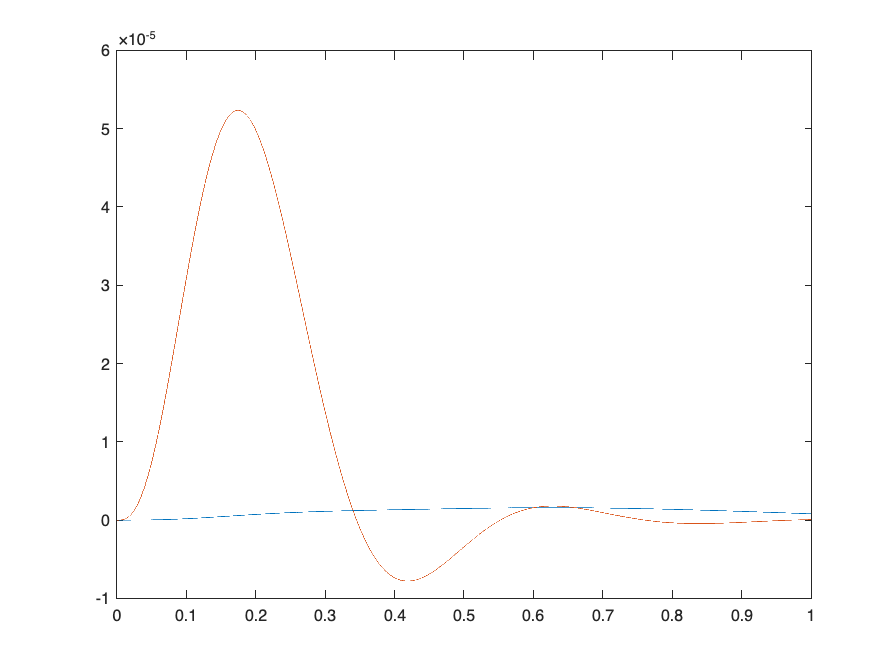


figure
t = 0:1e-5:1;
u = [sin(1e4*t); sin(1e4*t)];
[y_out, time] = lsim(G_feedback, u, t);
plot(time, y_out)


% figure
% t = 0:1e-5:10;
% u = [sin(10*t); sin(1e4*t)];
% [y_out, time] = lsim(G_feedback, u, t);
% plot(time, y_out)
% 
% 
% figure
% t = 0:1e-5:10;
% u = [sin(1e4*t); sin(10*t)];
% [y_out, time] = lsim(G_feedback, u, t);
% plot(time, y_out)

#### c)

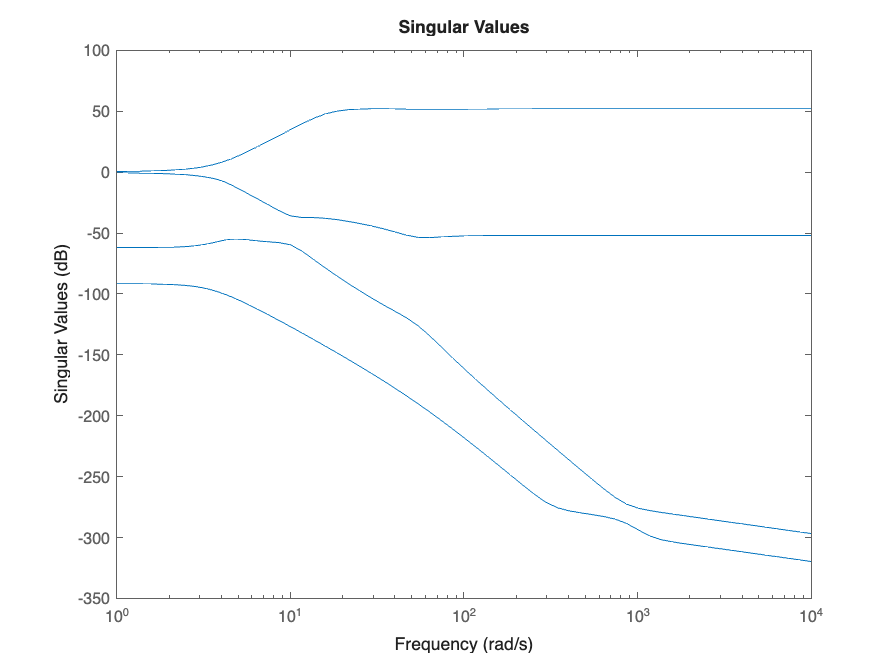

sigma(G_full_fb)

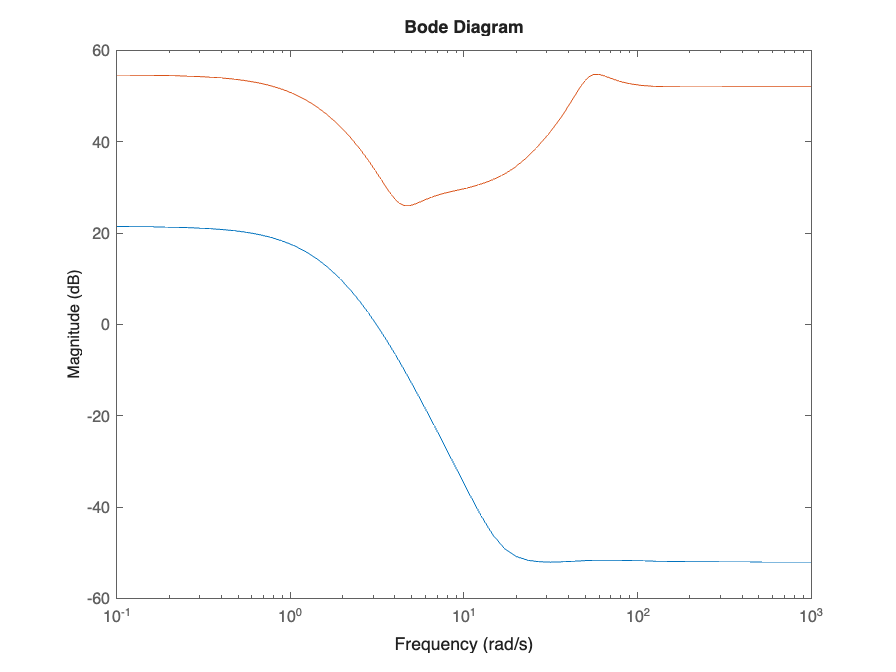


tfs = tf(G_full_fb);
Gq1_fh = tfs(1, 1);
Gfe_q2 = tfs(2, 2);
% sigma(tfs(1:2, 1:2));
bodemag(Gq1_fh^-1, Gfe_q2^-1)

The close loop behaviour is not very robust since Hinfnorm of G or r=> f is 400 (and this get worse as gamma is decreased less than 0.1) which mean the disturance in the system can only be 1/400 which is vary small

however this happens at high frequency, from q1 = > Fe whcih means that if a low pass filter is applied to the controller side this issue can be solved easily since in surgery the frequency of input nor output is expected to be high frequenct so this could be fine

## ii)

#### a)

not wriitng that either

#### b)

s = tf('s');
tau = 0.05;
X = 1/(tau*s + 1)^2;

G = [[1/s, X/s 1/s, 0];
    [X/s, 1/s, 0, 1/s];
    [(1-X)/(s^2), (X-1)/(s^2), s^(-2), -s^(-2)];
    [(1-X)/s, (X-1)/s, 1/s, -1/s]];

Gss  = ss(makeStateSpace(G), 'minimal');
% isPassive(Gss)
% step(Gss)

% sigma(Gss)
% hinfnorm(Gss)

% isproper(minreal(Gss))

% figure
% [Gss, Gred_info] = ncfmr(minreal(Gss), 5)
% reducespec(Gss, 'ncf')

A = Gss.A;
B = Gss.B;
C = Gss.C;
D = Gss.D;
Bf = B(:, 1:2);
Bu = B(:, 3:4);
% Df = D(:, 1:2);
% Du = D(:, 3:4);
Dfq = D(1:2, 1:2);
Duq = D(1:2, 3:4);
Dfe = D(3:4, 1:2);
Due = D(3:4, 3:4);
Cq = C(1:2, :);
Ce = C(3:4, :);


[n, n] = size(A);

ep = 0;
gamma=0;

cvx_begin sdp
    variable Q(n, n) symmetric
    variable Y(2, n)
    variable ep
    variable gamma
    minimize(ep+gamma)
    LMI1 = Q>0

 
Constraint accepted
 


    LMI2 = ep > 0

 
Constraint accepted
 


    LMI3 = [Q*A' + A*Q + Bu*Y + Y'*Bu', Bf - Q*Cq' - Y'*Duq';
            Bf' - Cq*Q - Duq*Y, -2*ep*eye(2) - (Dfq + Dfq')] < 0;

    LMI4 = gamma > 0.100000001

 
Constraint accepted
 


    LMI5 = [[Q*A' +  A*Q + Y'*Bu' + Bu*Y , Bf, Q*Ce' + Y'*Due' ];
                [ Bf', -gamma*eye(2) , Dfe'];
                [ Ce*Q + Due*Y , Dfe , -gamma*eye(2)]] < 0;


cvx_end

 
Calling SDPT3 4.0: 141 variables, 44 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 44
 dim. of sdp    var  = 27,   num. of sdp  blk  =  3
 dim. of linear var  =  2
 number of nearly dependent constraints = 1
 To remove these constraints, re-run sqlp.m with OPTIONS.rmdepconstr = 1.
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.3e+03|1.8e+01|4.1e+04| 8.800000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.384|0.867|1.4e+03|2.4e+00|4.2e+04|-7.565663e+00 -2.923563e+02| 0:0:00| chol  1  1 
 2|0.9

gamma

gamma = 0.1000


ep

ep = 1.9782e-07

K = Y/Q;

K_full = [zeros(2, n); K];

G_feedback = ss((A+Bu*K), Bf, (Cq + Duq*K), Dfq);
out= ["False", "True"];
disp("Is f to qdot passive: "+ out(1+isPassive(G_feedback)))

Is f to qdot passive: True



Gfb_full = ss((A+B*K_full), B, (C + D*K_full), D);
% Gfe = ss((A+Bf*K), Bf, (Ce + Due*K), Due);

tfs = tf(Gfb_full);

disp(['Hinfnorm of f to e :', num2str(hinfnorm(tfs(3:4, 1:2)))]);

Hinfnorm of f to e :0.0049447


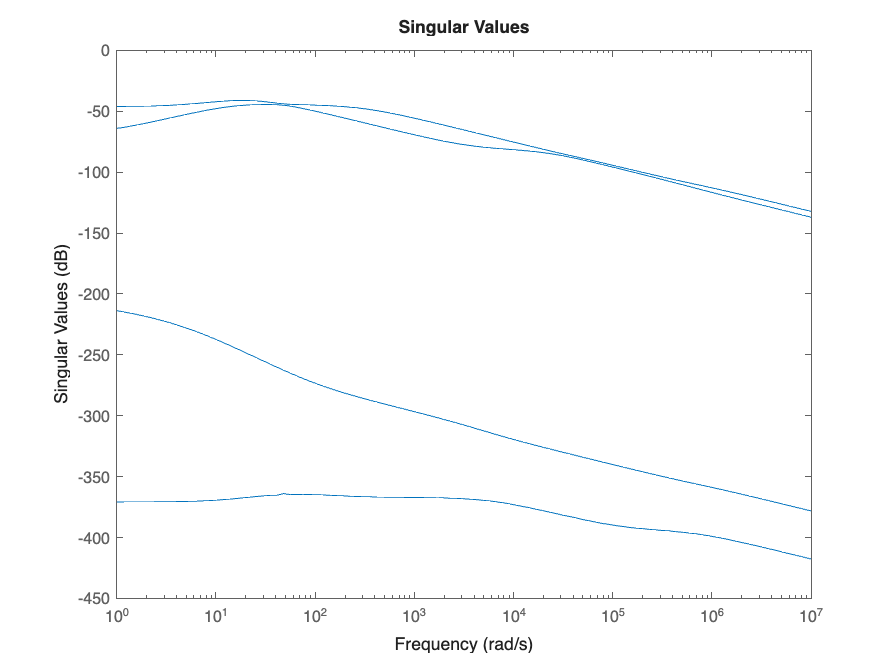


figure
sigma(Gfb_full)

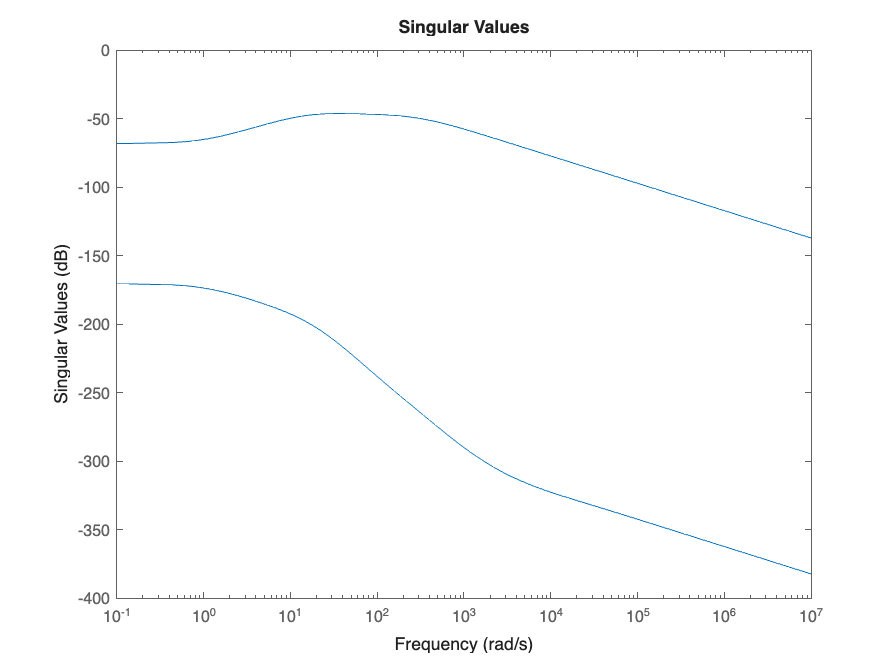


figure
sigma(tfs(3:4, 1:2))

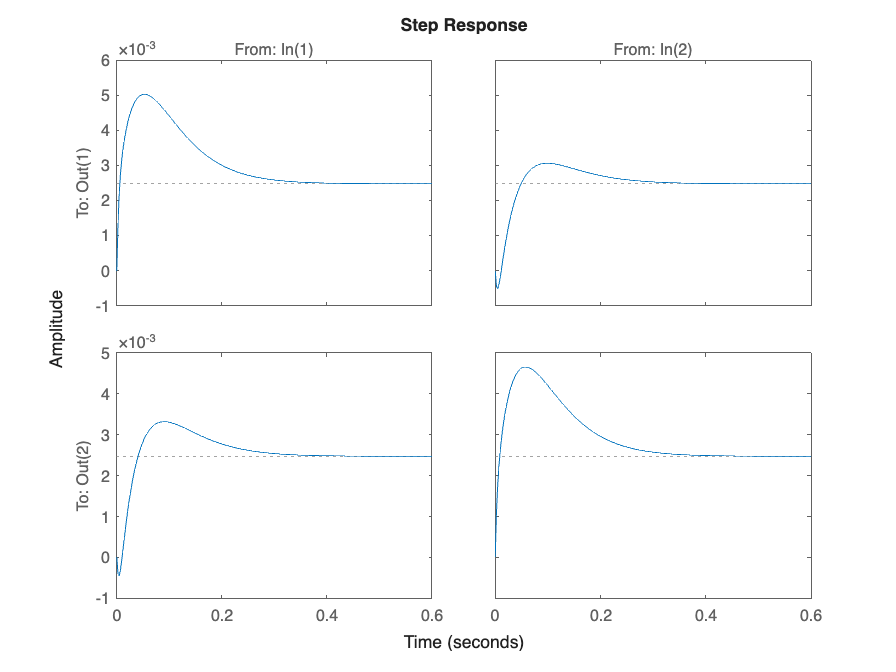

% sigma(tfs(3:4, 1:2))
% bode(tfs(1:2, 1:2))
% hinfnorm(tfs(3:4, 1:2))

figure
step(G_feedback)

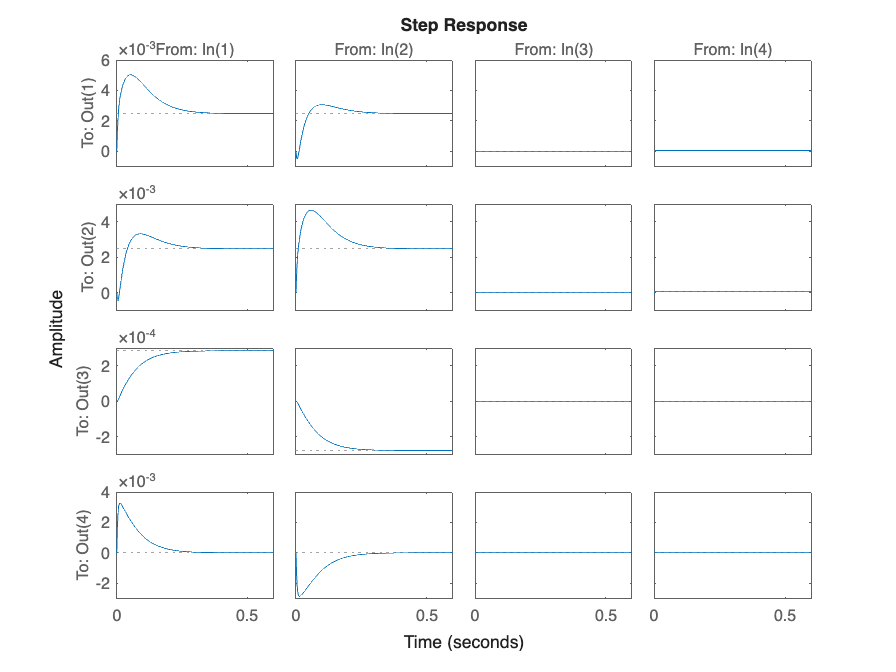


figure
step(Gfb_full)

% t = 0:1e-2:1;
% u = [sin(0.1*t.^2), sin(0.1*t.^2), sin(0.1*t.^2), sin(0.1*t.^2)];
% [time, y_out] = lsim(Gfb_full, u, t);
% plot(y_out, time)

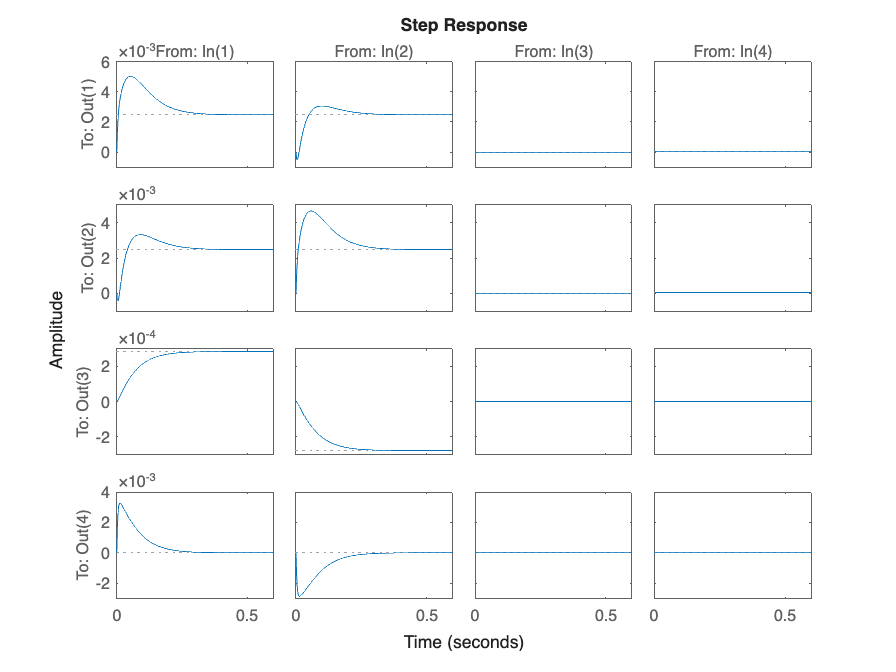

figure
step(Gfb_full)

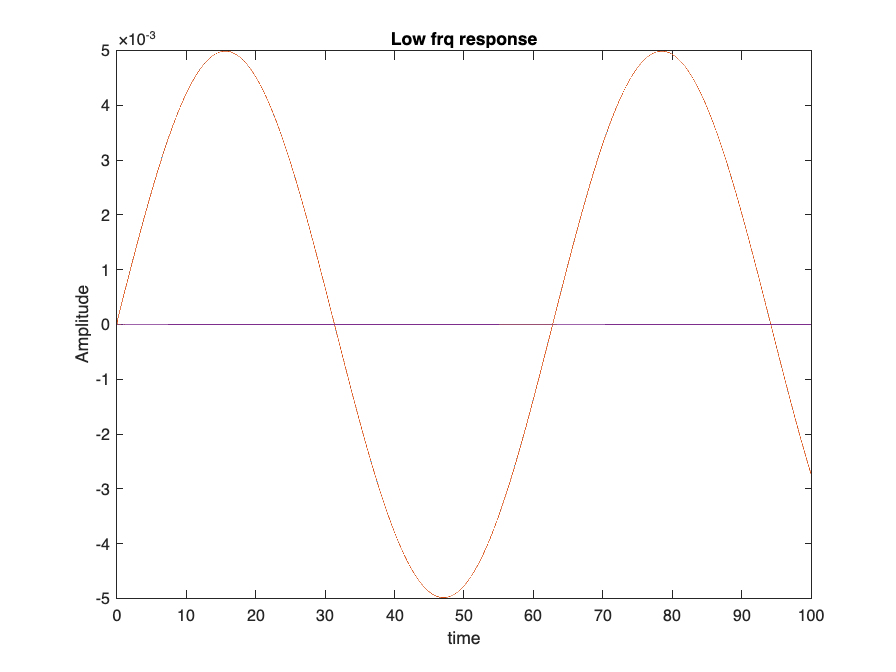

t = 0:1e-2:100;
omega = 0.1;
u = [sin(omega*t); sin(omega*t); sin(omega*t); sin(omega*t)];
[time, y_out] = lsim(Gfb_full, u, t);
plot(y_out, time)
xlabel('time')
ylabel('Amplitude')
title('Low frq response')

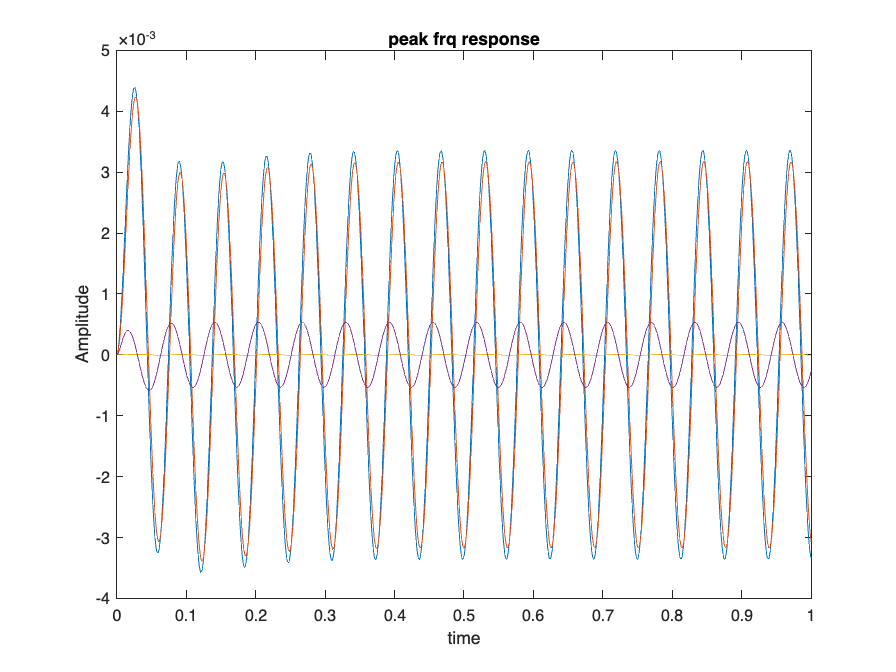


% 
% figure
% step(Gfb_full)
t = 0:1e-3:1;
omega = 100;
u = [sin(omega*t); sin(omega*t); sin(omega*t); sin(omega*t)];
[time, y_out] = lsim(Gfb_full, u, t);
plot(y_out, time)
xlabel('time')
ylabel('Amplitude')
title('peak frq response')

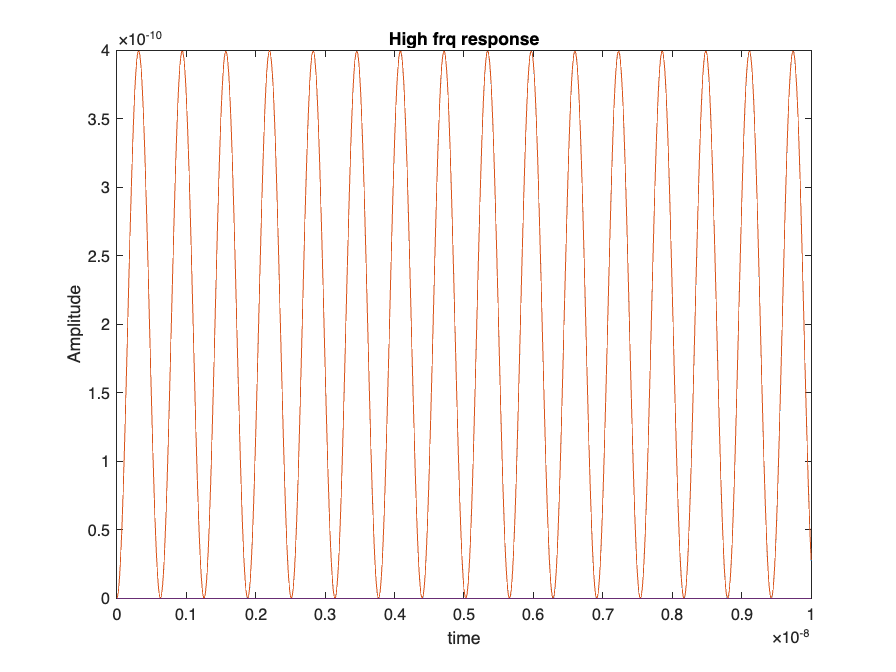



% figure
% step(Gfb_full)
t = 0:1e-11:1e-8;
omega = 1e10;
u = [sin(omega*t); sin(omega*t); sin(omega*t); sin(omega*t)];
[time, y_out] = lsim(Gfb_full, u, t);
plot(y_out, time)
xlabel('time')
ylabel('Amplitude')
title('High frq response')

### iii)

Hinf => insures robustness hard to form => can fine tune performance

Passivity => easy to formulate for some models and the system performs somewhat well but cant tune the performac as much as hinf lets you

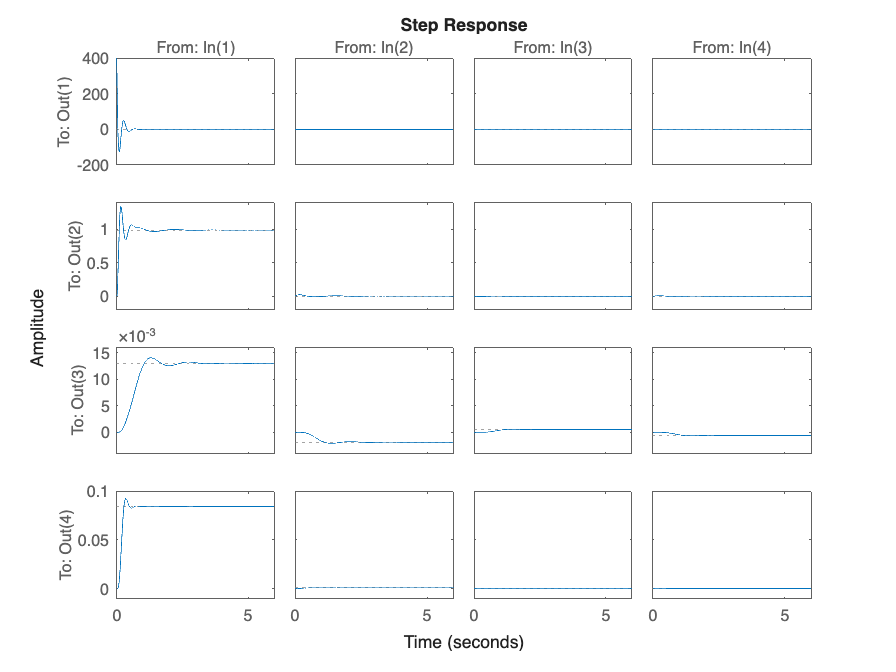

figure
step(G_full_fb)

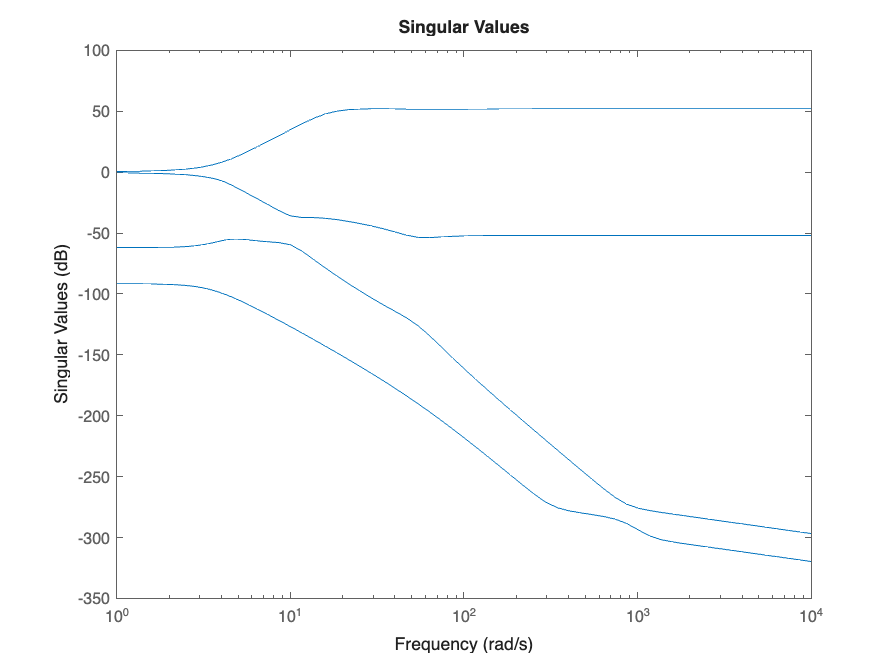

figure
sigma(G_full_fb)

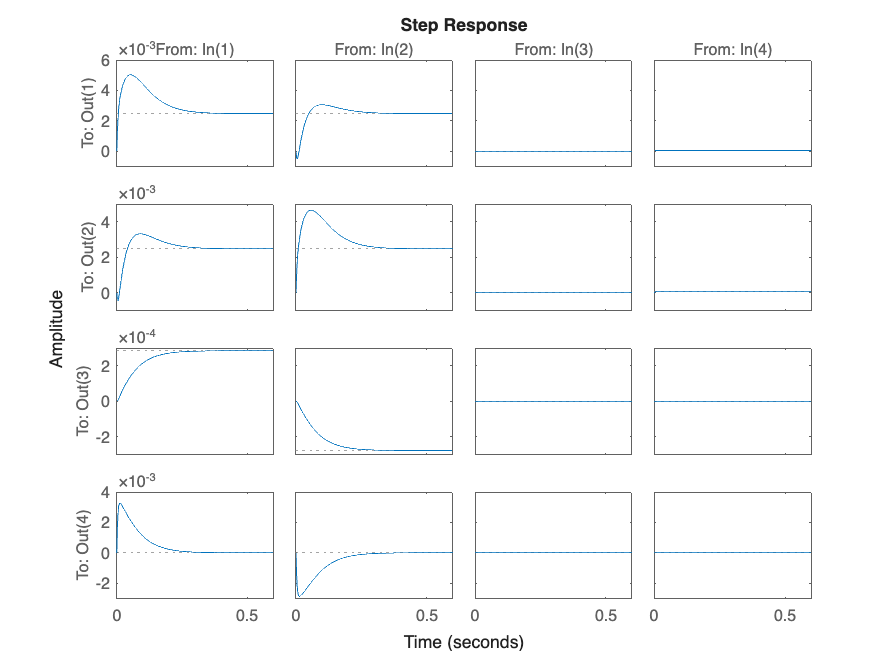


figure
step(Gfb_full)

figure
sigma(Gfb_full)